**Project - Equations of motion matlab script**

**Initialize**

%syms mc mp x dx l th dth g F Fcart Fpend ddx ddth s Fdist b
mc=0.9+0.1; 
mp=0.08887;
l= 0.36022;
g = 9.82;
b = 8.5;

**Without Disturbance linear**

% E = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fpend];
% S = solve(E,ddx,ddth);
% S.ddx;
% S.ddth;

**With Disturbance linaer**

% E1 = [(mc+mp)*ddx + mp*l*ddth == F-Fcart, mp*l^2*ddth-mp*ddx*l-mp*g*l*th == -Fdist-Fpend];
% S1 = solve(E1,ddx,ddth);
% S1.ddx;
% S1.ddth;

**Nonlinear**

% E2 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-Fcart, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -Fpend];
% S2 = solve(E2, ddx, ddth);
% S2.ddx;
% S2.ddth;

**Fpend and Fcart are b * x/th**

% E3 = [(mc+mp)*ddx + mp*l*ddth*cos(th)-mp*l*dth^2*sin(th) == F-b*dx, mp*l^2*ddth+mp*ddx*l*cos(th)-mp*g*l*sin(th) == -b*dth];
% S3 = solve(E3, ddx, ddth);
% S3.ddx;
% S3.ddth;

**State Space Model**

C = [0 1 0 0;
     1 0 0 0];
s = tf('s'); 
S = [s 0 0 0;
     0 s 0 0;
     0 0 s 0;
     0 0 0 s];
  
A = [0 0 1 0;
     0 0 0 1;
     0 (-g*mp)/(mc+2*mp) 0 0;
     0 -(g*(mp+mc))/(l*(mc+2*mp)) 0 0];
  
B = [0 0;
     0 0;
     1/(mc+2*mp) 1/(l*(mc+2*mp));
     -1/(l*(mc+2*mp)) -(mc+mp)/(l^2*mp*(mc+2*mp))];

% u = [F-Fcart; -Fpend];
 
system = ss(A,B,C,0)

system =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -0.741       0       0
   x4       0   -25.2       0       0
 
  B = 
           u1      u2
   x1       0       0
   x2       0       0
   x3  0.8491   2.357
   x4  -2.357  -80.17
 
  C = 
       x1  x2  x3  x4
   y1   0   1   0   0
   y2   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



**Observability and Controlability**

observability = obsv(system);
rank(observability); % Full rank

controlability = ctrb(system);  
rank(controlability); % Full rank

## **Pole Placement Method**

**Extended Matrices**

A_e = [A zeros([4 2]);
       C zeros([2 2])];
B_e = [B;
       zeros([2 2])];
C_e = [C zeros([2 2])];

**Pole Placement - settling of +/-3% in 1 second.**

ts = 1;
alpha = 3;
sigma = -log10((alpha/100)/100)/ts;

poles = -[sigma+1i sigma-1i sigma*5+1i sigma*5-1i sigma*6+1i sigma*6-1i];
% Tried to plot with poles on the real axis. This did not work either.
% poles = -[sigma sigma*5 sigma*7 sigma*12 sigma*18 sigma*22]

% Fe = -place(A_e, B_e, poles);
% F = Fe(1:2, 1:4);
% Fi = Fe(1:2, 5:6);

feedback = A_e + B_e * Fe;
eigMat = eig(A_e + B_e * Fe);

## **Transfer functions and PID controller **

## **Not used yet.**

G8 = C*inv(S-A)*B

G8 =
 
  From input 1 to output...
                -2.357
   1:  ------------------------
       s^2 + 1.218e-13 s + 25.2
 
                   0.8491 s^4 + 3.234e-15 s^3 + 23.15 s^2 + 1.052e-13 s - 1.59e-13
   2:  ----------------------------------------------------------------------------------------
       s^6 + 6.575e-15 s^5 + 25.2 s^4 + 1.879e-13 s^3 - 1.872e-13 s^2 - 5.178e-28 s + 1.544e-43
 
  From input 2 to output...
                -80.17
   1:  ------------------------
       s^2 + 1.218e-13 s + 25.2
 
                    2.357 s^4 + 8.978e-15 s^3 + 118.8 s^2 + 4.43e-13 s - 4.413e-13
   2:  ----------------------------------------------------------------------------------------
       s^6 + 6.575e-15 s^5 + 25.2 s^4 + 1.879e-13 s^3 - 1.872e-13 s^2 - 5.178e-28 s + 1.544e-43
 
Continuous-time transfer function.




[Gnum,Gden] = ss2tf(A,B,C,[0 0; 0 0], 1);
SS2TF1 = Gnum(1,:);
SS2TF2 = Gnum(2,:);
 
G1 =tf(SS2TF1, Gden)

G1 =
 
    -2.357 s^2
  --------------
  s^4 + 25.2 s^2
 
Continuous-time transfer function.



G2 =tf(SS2TF2, Gden)

G2 =
 
  0.8491 s^2 + 23.15
  ------------------
    s^4 + 25.2 s^2
 
Continuous-time transfer function.



**PID**

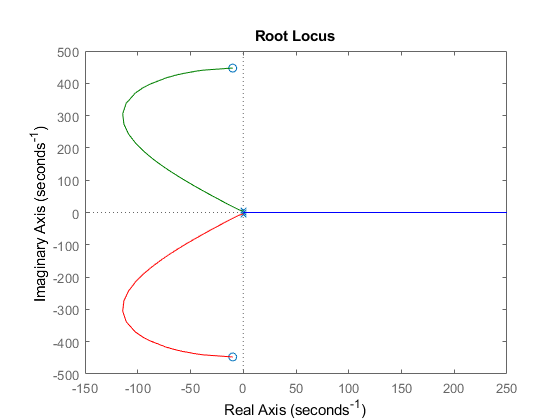

Kp = 50;
Ti = 0.0001;
Td = 0.05;

Ks = Kp * (1 + 1 / (Ti * s) + Td * s);
rlocus(Ks*G1);

% step(Ks*G2);

% pid(Kp,Ti,Td)


% rlocus(G1);
% rlocus(G2);
% It uses rational numbers instead of decimals.
%  G = C*inv((s-A))*B*u
%  simplify(G);